# Sinusfahrt zur Abschätzung der Kameraverzögerung

Dieses Skript dient der Ermittlung der Verzögerung der Kameradaten durch Berechnung der Roboterposition, Packen und Senden des UDP-Datenpakets.

Hierzu wird der Roboter in x-Achse mit einem Sin()-förmigen Geschwindikeitsverlauf angestuert. Die Verzögerung ermittelt sich entsprehcend aus der Pjhasendifferenz zwischen Encoderdaten und Kameradaten.

## Einlesen der Messwerte

clear all
clc, close all;
FIRST_MEASUREMENT_IDX = 2;
LAST_MEASUREMENT_IDX = 15000;

% Messwerte einlesen und Lücken in Daten durch Mittelwerte ersetzen
filename = "circles-2023-04-18-1244.csv";
data = readtable(filename);


% Zeitvektor
t = table2array(data(:,"Name"));
t = t(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX)/1000;

% Encoder-Daten
vX = table2array(data(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX,"vX"));
vY = table2array(data(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX,"vY"));
vTheta = table2array(data(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX,"vTheta"));

% Kameradaten
xCam = table2array(data(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX,"xCam"));
yCam = table2array(data(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX,"yCam"));
thetaCam = table2array(data(FIRST_MEASUREMENT_IDX:LAST_MEASUREMENT_IDX,"thetaCam"));

% Preprocessing der Kameradaten
oldTheta = 0;
for row = 1 : length(thetaCam)
    if thetaCam(row) == 0
        thetaCam(row) = oldTheta;
    else
        oldTheta = thetaCam(row);
    end
end

oldCamX = 0;
for row = 1 : length(xCam)
    if xCam(row) == 0
        xCam(row) = oldCamX;
    else 
        oldCamX = xCam(row);
    end
end



## Sinus-Approximation der globalen x-Geschwindigkeit (Encodern)

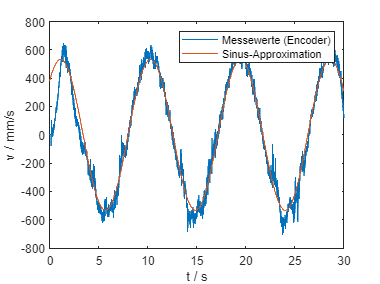

fncVelocity = @(x, b) (2*pi*b(2)*b(1)*cos(2*pi*b(2)*x + b(3)));
fitVelocity = @(b)(sum((fncVelocity(t',b)-vX').^2));
b0Velocity = [600, 1/8, 0, 0];
bVelocity = fminsearch(fitVelocity, b0Velocity);

figure()
plot(t, vX, t, fncVelocity(t, bVelocity));
legend('Messewerte (Encoder)', 'Sinus-Approximation')
xlabel("t / s")
ylabel("v / mm/s")

## Sinus-Approximation der x-Position (Kamera)

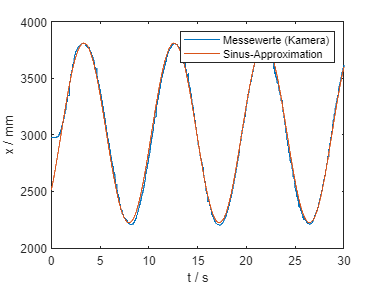

fncPosition = @(x, b) (b(1)*sin(2*pi*b(2)*x + b(3)) + b(4));
fitPosition = @(b)(sum((fncPosition(t',b)-xCam').^2));
b0Position = [980, 1/16, 0, 2.8380e+03];
bPosition = fminsearch(fitPosition, b0Position);

figure()
plot(t, xCam, t, fncPosition(t, bPosition));
legend('Messewerte (Kamera)', 'Sinus-Approximation')
xlabel("t / s")
ylabel("x / mm")

## Bestimmung des Kamera-Delays

% Phasendifferenz zwischen xCam und vXEncoder
phasePosition = bPosition(3)

phasePosition = -3.8316

phaseVelocity = bVelocity(3)

phaseVelocity = -0.7760

camDelayInRad = (phasePosition + pi/2) - phaseVelocity

camDelayInRad = -1.4848


averageCycleTime = (1 / bPosition(2) + 1 / bVelocity(2)) / 2

averageCycleTime = 9.2055

camDelayInSeconds = camDelayInRad / (2*pi) * averageCycleTime

camDelayInSeconds = -2.1754

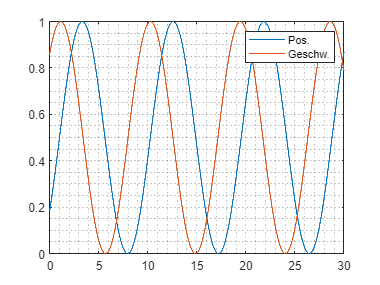

plot(t, rescale(fncPosition(t, bPosition)), t, rescale(fncVelocity(t, bVelocity)));
legend("Pos.", "Geschw.")
grid minor


position = fncPosition(t, bPosition);
position = position(1:5000);
velocity = fncVelocity(t, bVelocity);
velocity = velocity(1:5000);
[mPos, idxPos] = max(position);
[mVel, idxVel] = max(velocity);
camDelayInMilliSeconds = abs(idxPos - 0.25*averageCycleTime/0.002 - idxVel) * 2

camDelayInMilliSeconds = 103.3864